# Lecture: MATLAB Review 2 code

Kim Xu

MAE 284

## Area of a square function

A = 5;
new = sqArea(2)

new = 4

sqArea(5)

ans = 25

## Using the drop function

***How do you call the function if you need to use both the values from the function?***

% [distance, speed] = drop(10,5)

File: drop.m Line: 37 Column: 35
Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

***What do you do if you only want one?***

d = drop(10,5)
[~, v] = drop(10,5)

***What do you need to do to the function if you want to give a vector of time values as input?***

distances = drop(10, 5:0.5:7)

## Anonymous function 

$3x^3 +5x^2 -2x+1$*** solve for ***$x=2$

poly3 = @(x) 3*x.^3 + 5*x.^2 - 2*x + 1;
poly3(2)
poly3(2:4)

## If structure - Safe to divide by b?

noDivBy0(5, 0)
noDivBy0(5,2)

## If-else structure - don't make an imaginary number

noImaginary(5)
noImaginary(-5)

## If-elseif-else structure

absDist(5,5)
absDist(5,2)
absDist(2,5)

## Further modifications of drop function

***Make it handle values in meters or feet***

distance = drop(10,5, 'm')
distance = drop(10,5, 'ft')

***Give an error message if the user doesn’t provide enough inputs***

% drop(10)

***The default value should be meters***

dist = drop(10,5)

***Demonstrate lack of vector error***

drop(10,5)

***Demonstrate plotting***

%drop(10,linspace(2,10))

## Helper functions

### **sqArea function**

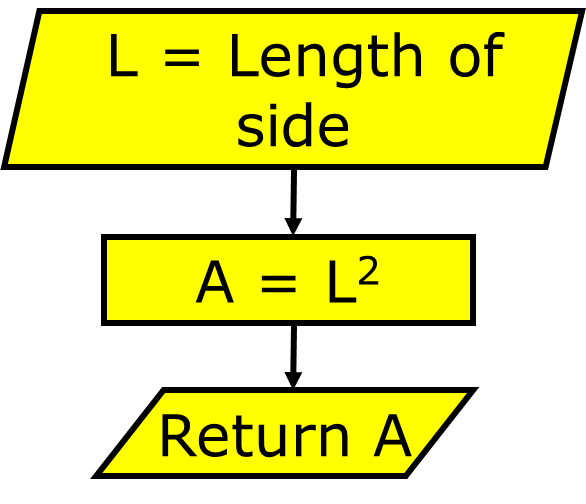

function area = sqArea(L)

area = L^2;

end

### noDivBy0 function

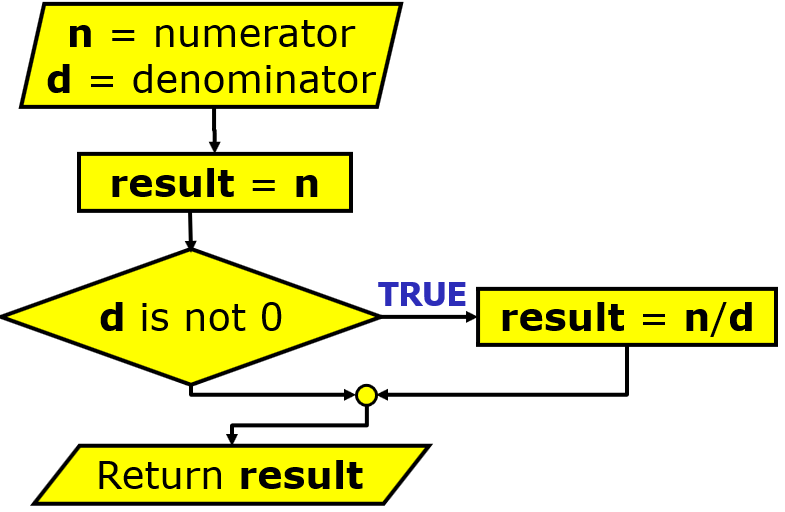

function result = noDivBy0(n, d)
% NODIVBY0 divides the value n by the value d, unless d equals 0, then the
% result is the numerator
% Created by:
% ARGUMENTS:
%   n - numerator
%   d - denominator
% RETURNS:
%   result - if d is 0, result is n, otherwise result is n/d
result = n;
if d ~= 0
    result = n/d;
end
end

### noImaginary function

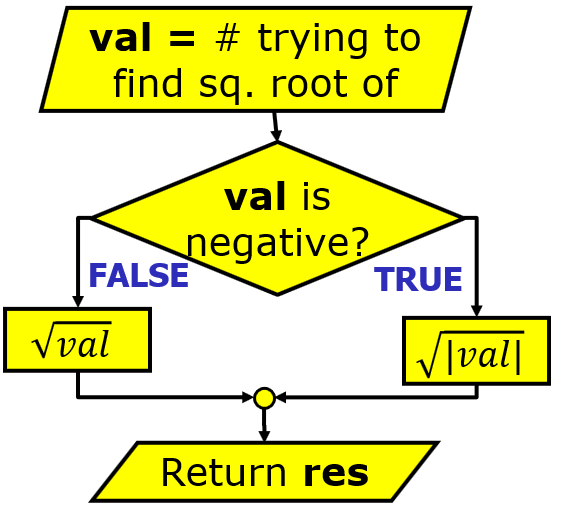

function res = noImaginary(val)
if val < 0
    res = sqrt(abs(val));
else
    res = sqrt(val);
end
end

### absDist function

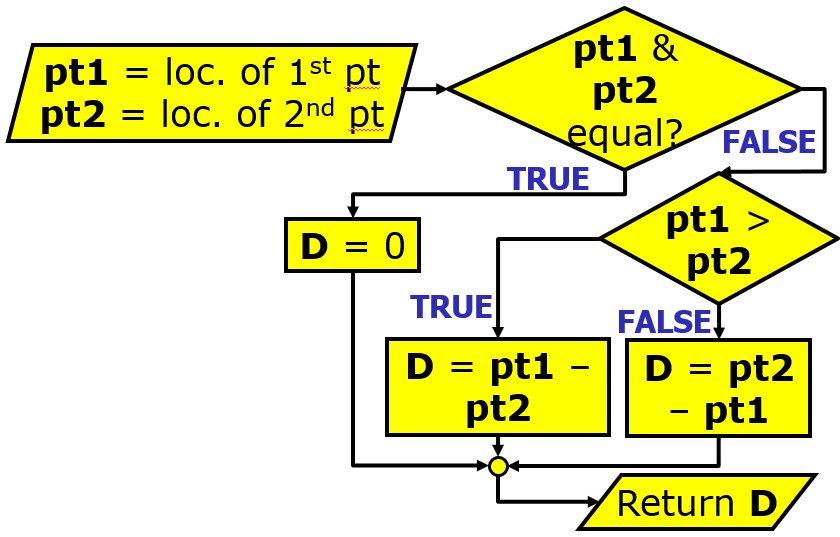

function D = absDist(pt1, pt2)
if pt1 == pt2
    D = 0;
elseif pt1 > pt2
    D = pt1 - pt2;
else
    D = pt2 - pt1;
end
end